# Allow access to files

addpath('Archive');
addpath('Control');
addpath('Data');
addpath('ID_functions');
addpath('Simulation_functions');
addpath('Simulink_files');

# Step 1: Reaction Wheel

parameters = struct;
h = 0.01;

% Data preparation
load('signal_3_12_5.mat');
y = angular_velocity.data(2:end);

[bphi, Jphi, k] = flywheel_ID(u', y, h);
parameters.bphi = bphi;
parameters.Jphi = Jphi;
parameters.k = k;

# Part 2 : Pendulum

%clearvars -except parameters h

% Data preparation
load('signal_2_1_6.mat');
y = pendulum_angle.data(2:end);

[m, l, btheta, Jtheta] = pendulum_ID(u, y, h);
parameters.m = m;
parameters.l = l;
parameters.btheta = btheta;
parameters.Jtheta = Jtheta;

# Section 3 : Both

%clearvars -except parameters h

% Data preparation
load('signal_1f_1_6.mat');
% load('chirp.mat')
y1 = pendulum_angle.data(2:end);
y2 = angular_velocity.data(2:end);
u = u(2:end);

% y = zeros(length(y1),1);
% for i = 1:length(y1)
%     y((i-1)*2+1) = y1(i);
%     y(i*2) = y2(i);
% end

[final_parameters, A, B, C, D, sys] = full_system_ID(u,[y1 y2], h, parameters);

# Chapter 4 : Nonlinear Validation

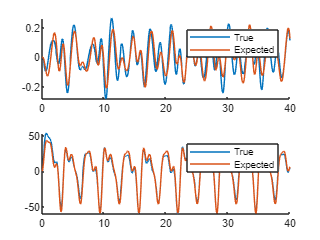

A = sys.A; B = sys.B; C = sys.C; D = sys.D;
load('signal_1h_1_6.mat')
t = 0:h:(length(u)*h)-h;
y2 = angular_velocity.data;
y1 = pendulum_angle.data;
y1 = y1(2:end);
y2 = y2(2:end);
[yhat,xhat] = simsystem(A,B,C,[y1(1), 0.9*(y1(5)-y1(1))/(4*h), y2(1)], u);
y1hat = yhat(1:2:end); y2hat = yhat(2:2:end);

figure;
tiledlayout(1,2);
title("Verification Comparison")
nexttile
hold on
plot(0:h:(length(y1)*h-h),y1);
plot(t,y1hat);
legend("True", 'Expected');
nexttile
hold on
plot(0:h:(length(y2)*h-h),y2);
plot(t,y2hat);
legend("True", 'Expected');


A_bottom = A;

# Segment 5 : Flipping upside down

sysc = d2c(idss(sys))

sysc =
  Continuous-time identified state-space model:
      dx/dt = A x(t) + B u(t) + K e(t)
       y(t) = C x(t) + D u(t) + e(t)
 
  A = 
               x1          x2          x3
   x1  -1.436e-14           1  -9.146e-21
   x2      -9.886  -2.234e-06    0.004799
   x3           0           0      -1.044
 
  B = 
              u1
   x1  3.472e-18
   x2     -3.663
   x3      421.3
 
  C = 
       x1  x2  x3
   y1   1   0   0
   y2   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
 
  K = 
       y1  y2
   x1   0   0
   x2   0   0
   x3   0   0
 
Parameterization:
   FREE form (all coefficients in A, B, C free).
   Feedthrough: none
   Disturbance component: none
   Number of free coefficients: 18
   Use "idssdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                         
Created by direct construction or transformation. Not estimated.


sysc.A(2,1) = -sysc.A(2,1);
sys = c2d(sysc, h, 'zoh');
A = sys.A; B = sys.B; C = sys.C; D = sys.D;

%clearvars -except A B C D h